clear all

% Define symbolic variables
syms theta alpha theta_dot alpha_dot u real
% syms Jr mp Lr Lp Jp lp g Br Bp

mp = 0.1;   % mass of the pendulum [kg]
Lp = 0.3;   % length of the pendulum [m]
lp = 0.15;  % position of the center of mass of the pendulum [m]
Jp = 0.003; % moment of inertia of the pendulum [kg*m^2]
Lr = 0.15;  % length of the rotary arm [m]
Jr = 0.01;  % moment of inertia of the rotary arm [kg*m^2]
Bp = 0.4;   % viscous friction coefficient of the pendulum [Nms/rad]
Br = 0.2;   % viscous friction coefficient of the rotary arm [Nms/rad]
g = 9.81;   % gravity constant [m/s^2]


% Define the matrices
M = [Jr + mp * (Lr^2 + lp^2 * (1 - cos(alpha)^2)), mp*lp*Lr*cos(alpha);
     mp*lp*Lr*cos(alpha), Jp + mp*lp^2];


C = [2*mp*lp^2*alpha_dot*sin(alpha)*cos(alpha), -mp*lp*Lr*alpha_dot*sin(alpha);
     -mp*lp^2*theta_dot*sin(alpha)*cos(alpha), 0];

fv = [Br*theta_dot;
      Bp*alpha_dot];
G = [0;
     -mp*lp*g*sin(alpha)];

tau = [u;
       0];
q = [theta; alpha];
q_dot = [theta_dot; alpha_dot];
x = [q; q_dot]

$$x = \left(\begin{array}{c} \theta \\ \alpha \\ \dot{\theta }\\ \dot{\alpha } \end{array}\right)$$

q_ddot = inv(M)*(tau - C*q_dot - fv - G)

$$q\_ddot = \begin{array}{l} \left(\begin{array}{c} \frac{14000\,\sigma_{1}}{45\,{\cos\left(\alpha \right)}^{2}-203}+\frac{6000\,\cos\left(\alpha \right)\,\sigma_{2}}{45\,{\cos\left(\alpha \right)}^{2}-203}\\ \frac{2000\,\left(9\,{\cos\left(\alpha \right)}^{2}-58\right)\,\sigma_{2}}{3\,\left(45\,{\cos\left(\alpha \right)}^{2}-203\right)}-\frac{6000\,\cos\left(\alpha \right)\,\sigma_{1}}{45\,{\cos\left(\alpha \right)}^{2}-203} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{9\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}}{4000}+\frac{9\,\dot{\theta }\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,\dot{\alpha }}{2000}+\frac{\dot{\theta }}{5}-u\\ \sigma_{2}=\frac{9\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,{\dot{\theta }}^{2}}{4000}-\frac{2\,\dot{\alpha }}{5}+\frac{2943\,\sin\left(\alpha \right)}{20000} \end{array}$$

sympref('AbbreviateOutput',true)

ans = logical
   1


f = [q_dot;q_ddot];

f_handle = matlabFunction(f, 'Vars', {theta, alpha, theta_dot, alpha_dot, u});
taylor_expansion = taylor(f, x, [0,0,0,0], 'Order', 2)

$$taylor\_expansion = \left(\begin{array}{c} \dot{\theta }\\ \dot{\alpha }\\ \frac{1200\,\dot{\alpha }}{79}-\frac{8829\,\alpha }{1580}-\frac{1400\,\dot{\theta }}{79}+\frac{7000\,u}{79}\\ \frac{48069\,\alpha }{1580}-\frac{19600\,\dot{\alpha }}{237}+\frac{600\,\dot{\theta }}{79}-\frac{3000\,u}{79} \end{array}\right)$$

f_handle(1,1,1,1,1)

ans =     1.0000
    1.0000
   63.6767
  -67.1552


A_simb_full = jacobian(f, x)

B_simb_full = jacobian(f, u)

$$B\_simb\_full = \left(\begin{array}{c} 0\\ 0\\ -\frac{14000}{45\,{\cos\left(\alpha \right)}^{2}-203}\\ \frac{6000\,\cos\left(\alpha \right)}{45\,{\cos\left(\alpha \right)}^{2}-203} \end{array}\right)$$



%% TRUNCATE 
% We approximate the function doing a Second Order Approximation
taylor_expansion = taylor(f, x, [0,0,0,0], 'Order', 2)

$$taylor\_expansion = \left(\begin{array}{c} \dot{\theta }\\ \dot{\alpha }\\ \frac{1200\,\dot{\alpha }}{79}-\frac{8829\,\alpha }{1580}-\frac{1400\,\dot{\theta }}{79}+\frac{7000\,u}{79}\\ \frac{48069\,\alpha }{1580}-\frac{19600\,\dot{\alpha }}{237}+\frac{600\,\dot{\theta }}{79}-\frac{3000\,u}{79} \end{array}\right)$$



A = double(jacobian(taylor_expansion, x))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -5.5880  -17.7215   15.1899
         0   30.4234    7.5949  -82.7004


B = double(jacobian(taylor_expansion, u))

B =          0
         0
   88.6076
  -37.9747




% Linearize around the equilibrium point x = [0; 0; 0; 0]
q0 = [0.05;0;0.06;0];
% x = [theta; alpha; theta_dot; alpha_dot];
f_handle = matlabFunction(f, 'Vars', {theta, alpha, theta_dot, alpha_dot, u})

f_handle = function_handle with value:
    @(theta,alpha,theta_dot,alpha_dot,u)[theta_dot;alpha_dot;((theta_dot./5.0-u-alpha_dot.^2.*sin(alpha).*2.25e-3+alpha_dot.*theta_dot.*cos(alpha).*sin(alpha).*4.5e-3).*1.4e+4)./(cos(alpha).^2.*4.5e+1-2.03e+2)+(cos(alpha).*(alpha_dot.*(-2.0./5.0)+sin(alpha).*1.4715e-1+theta_dot.^2.*cos(alpha).*sin(alpha).*2.25e-3).*6.0e+3)./(cos(alpha).^2.*4.5e+1-2.03e+2);(cos(alpha).*(theta_dot./5.0-u-alpha_dot.^2.*sin(alpha).*2.25e-3+alpha_dot.*theta_dot.*cos(alpha).*sin(alpha).*4.5e-3).*-6.0e+3)./(cos(alpha).^2.*4.5e+1-2.03e+2)+((cos(alpha).^2.*9.0-5.8e+1).*(alpha_dot.*(-2.0./5.0)+sin(alpha).*1.4715e-1+theta_dot.^2.*cos(alpha).*sin(alpha).*2.25e-3).*6.666666666666667e+2)./(cos(alpha).^2.*4.5e+1-2.03e+2)]


f_handle(1,1,1,1,1)

ans =     1.0000
    1.0000
   63.6767
  -67.1552


% Display the results
disp('Linearized state-space representation:');

Linearized state-space representation:


disp('A = ');

A = 


disp(A);

         0         0    1.0000         0
         0         0         0    1.0000
         0   -5.5880  -17.7215   15.1899
         0   30.4234    7.5949  -82.7004



disp('B = ');

B = 


disp(B);

         0
         0
   88.6076
  -37.9747




[n,~] = size(A); %[n x n]
[~,p] = size(B); %[n x p]


%% Stability: Eigenvalues Test
ev = real(eig(A)); %real part of the eigenvalues of A

disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp('Internal Stability Test (open-loop)')

Internal Stability Test (open-loop)


disp('*Eigenvalues test:')

*Eigenvalues test:


if all(ev<0)
    disp(['    ' 'all eigenvalues have negative real part --> system is stable'])
else
    disp(['    ' 'at least one eigenvalue has positive real part --> system is unstable'])
end

    at least one eigenvalue has positive real part --> system is unstable


disp('*Open-loop eigenvalues real parts: ')

*Open-loop eigenvalues real parts: 


disp(['    ', mat2str(ev')]);

    [0 -84.7869112636998 0.36611872412553 -16.0011483886957]




ctrb(A,B)

ans = 1.0e+07 *

         0    0.0000   -0.0002    0.0096
         0   -0.0000    0.0004   -0.0333
    0.0000   -0.0002    0.0096   -0.6782
   -0.0000    0.0004   -0.0333    2.8373



%% Controllability Test
ctr = rank(ctrb(A,B)); %controllability matrix

disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp('Controllability Test');

Controllability Test


disp('*Controllability matrix test:');

*Controllability matrix test:


if ctr==n
    disp(['    ' 'ctrb matrix is full rank --> system is controllable'])
else
    disp(['    ' 'ctrb matrix is rank deficient --> system is NOT controllable'])
    disp('*plant dimension:');
    disp(['    ', num2str(n)]);
    disp('*ctrb matrix rank:');
    disp(['    ', num2str(ctr), newline]);
end

    ctrb matrix is full rank --> system is controllable


**Checking asymptotic stability of the system using LMIs**

yalmip('clear'); %clear the memory of the solver

% -- Define settings to give to the solver
opts = sdpsettings('solver', 'mosek', 'verbose', 0);


% -- Define variables to be used in the optimization problem
P = sdpvar(n,n);
fake_zero = 1e-3;

% -- Define LMIs are constraints of the optmization problem
constr = [P >= fake_zero*eye(n);
          A'*P + P*A <= -fake_zero*eye(n)];
      
% -- Solve the opmtimization problem
sol = solvesdp(constr, [], opts);

% -- Extract the numerical values of P
P_value = value(P);

% -- Check that the problem was successfully solved
[primal_res, dual_res] = check(constr); %residuals of the constraints

% -- All the residuals must be greater than zero. Sometimes you can accept
% slightly negative residuals
feas = all([primal_res; dual_res] > -fake_zero);

disp(newline);
disp('-----------------------')

-----------------------


disp('Checking asymptotic stability using the LMI condition');

Checking asymptotic stability using the LMI condition


if( feas )
    disp('The LMI is feasible, the system is AS');
else
    disp('The LMI is infeasible, the system is NOT AS');
end

The LMI is infeasible, the system is NOT AS


**Feedback design: desired Convergence Rate**

% -- Clear the internal memory of YALMIP
yalmip('clear')
opts = sdpsettings('solver', 'mosek', 'verbose', 0);
simT = 0:0.01:6;

% -- Optimization variables
W = sdpvar(n,n);
X = sdpvar(p,n);
fake_zero = 1e-3;

% -- Constraints
alpha_b = 2;
constr = [ W >= fake_zero*eye(n)                ;...
          (A*W+B*X)+(A*W+B*X)' <= -2*alpha_b*W ];
      
% -- Solve the problem
sol = solvesdp(constr,[],opts);

% -- extract the results
W_b = value(W);
X_b = value(X);
K_b = X_b*inv(W_b);

% -- Check constraints
[primalfeas,dualfeas] = check(constr);
disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp(['LMI Feedback design (alpha = ' num2str(alpha_b) ')'])

LMI Feedback design (alpha = 2)


disp('*Constraints check:')

*Constraints check:


if all([primalfeas;dualfeas] > -fake_zero)
    disp(['    ', 'Constraints are satisfied --> system is stable'])
    disp('*Gain matrix K:');
    disp(['    ', num2str(K_b)]);
else
    disp(['    ', 'Constraints are NOT satisfied --> system is unstable'])
end

    Constraints are satisfied --> system is stable


*Gain matrix K:


    8.6549215      5345.8148      29.679571      66.999083


disp('*Closed-loop eigenvalues real parts:')

*Closed-loop eigenvalues real parts:


disp(['    ' num2str(real(eig(A+B*K_b)'))]);

    -5.0814     -5.0814     -2.3464     -2.3464



% K_a
K_b

K_b = 1.0e+03 *

    0.0087    5.3458    0.0297    0.0670


P_b = inv(W_b);


f_handle = matlabFunction(f, 'Vars', {theta, alpha, theta_dot, alpha_dot, u})

f_handle = function_handle with value:
    @(theta,alpha,theta_dot,alpha_dot,u)[theta_dot;alpha_dot;((theta_dot./5.0-u-alpha_dot.^2.*sin(alpha).*2.25e-3+alpha_dot.*theta_dot.*cos(alpha).*sin(alpha).*4.5e-3).*1.4e+4)./(cos(alpha).^2.*4.5e+1-2.03e+2)+(cos(alpha).*(alpha_dot.*(-2.0./5.0)+sin(alpha).*1.4715e-1+theta_dot.^2.*cos(alpha).*sin(alpha).*2.25e-3).*6.0e+3)./(cos(alpha).^2.*4.5e+1-2.03e+2);(cos(alpha).*(theta_dot./5.0-u-alpha_dot.^2.*sin(alpha).*2.25e-3+alpha_dot.*theta_dot.*cos(alpha).*sin(alpha).*4.5e-3).*-6.0e+3)./(cos(alpha).^2.*4.5e+1-2.03e+2)+((cos(alpha).^2.*9.0-5.8e+1).*(alpha_dot.*(-2.0./5.0)+sin(alpha).*1.4715e-1+theta_dot.^2.*cos(alpha).*sin(alpha).*2.25e-3).*6.666666666666667e+2)./(cos(alpha).^2.*4.5e+1-2.03e+2)]



% -- Simulation
% [simT_a,simQ_a]  = ode45(@(t,q)f_handle(q(1),q(2),q(3),q(4),K_a*q),simT,q0); %simT è lo span per cui si integra
[simT_b,simQ_b]  = ode45(@(t,q)f_handle(q(1),q(2),q(3),q(4),K_b*q),simT,q0);


**Feedback design: desired Convergence Rate and minimum control effort**

% -- Clear the internal memory of YALMIP
yalmip('clear')

% -- Optimization variables
W = sdpvar(n,n);
X = sdpvar(p,n);
k = sdpvar(1,1);
fake_zero = 1e-3;
opts = sdpsettings('solver', 'mosek', 'verbose', 0);
simT = 0:0.01:6;

% -- Constraints
alpha_c = 2;
constr = [ W >= eye(n)               ;...
          (A*W+B*X)+(A*W+B*X)' <= -2*alpha_c*W ;...
          [ k*eye(n)      X'   ;...
               X      k*eye(p) ]   >= fake_zero*eye(n+p)];
% 
% constr = [ W >= fake_zero*eye(n)               ;...
%           (A*W+B*X)+(A*W+B*X)' <= -2*alpha_c*W ;...
%           [ k*eye(n)      X'   ;...
%                X      k*eye(p) ]   >= fake_zero*eye(n+p)];
% -- Solve the problem

sol = solvesdp(constr,k,opts);

% -- Extract the results
W_c = value(W);
X_c = value(X);
k_c = value(k);
K_c = X_c*inv(W_c)

K_c = 1.0e+03 *

    0.0053    3.0594    0.0171    0.0400



% -- Check constraints
[primalfeas,dualfeas] = check(constr);
disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp(['LMI Feedback design (alpha = ' num2str(alpha_c) ', minimize |K|)' ])

LMI Feedback design (alpha = 2, minimize |K|)


disp('*Constraints check:')

*Constraints check:


if all([primalfeas;dualfeas] > -fake_zero)
    disp(['    ' 'Constraints are satisfied --> system is stable'])
    disp('*Gain matrix K:');
    disp(['    ' num2str(K_c)]);
    disp(['*Minimum bound on gain matrix norm: |K| < ', num2str(k_c)]);
else
    disp(['    ', 'Constraints are NOT satisfied --> system is unstable'])
end

    Constraints are satisfied --> system is stable


*Gain matrix K:


    5.2553885      3059.3518       17.07226      39.953227


*Minimum bound on gain matrix norm: |K| < 16667788.9885


disp('Closed-loop eigenvalues real parts:')

Closed-loop eigenvalues real parts:


disp(['    ', num2str(real(eig(A+B*K_c)'))]);

    -84.8342     -16.0621     -2.00245     -2.00245


PROVA = A+B*K_c

PROVA = 1.0e+05 *

         0         0    0.0000         0
         0         0         0    0.0000
    0.0047    2.7108    0.0150    0.0356
   -0.0020   -1.1615   -0.0064   -0.0160


AUTO = eig(PROVA)

AUTO =  -84.8342 + 0.0000i
 -16.0621 + 0.0000i
  -2.0024 + 2.3598i
  -2.0024 - 2.3598i


% -- Simulation
[simT_c,simQ_c]  = ode45(@(t,q)f_handle(q(1),q(2),q(3),q(4),K_c*q),simT,q0);

**Plot the solutions:**

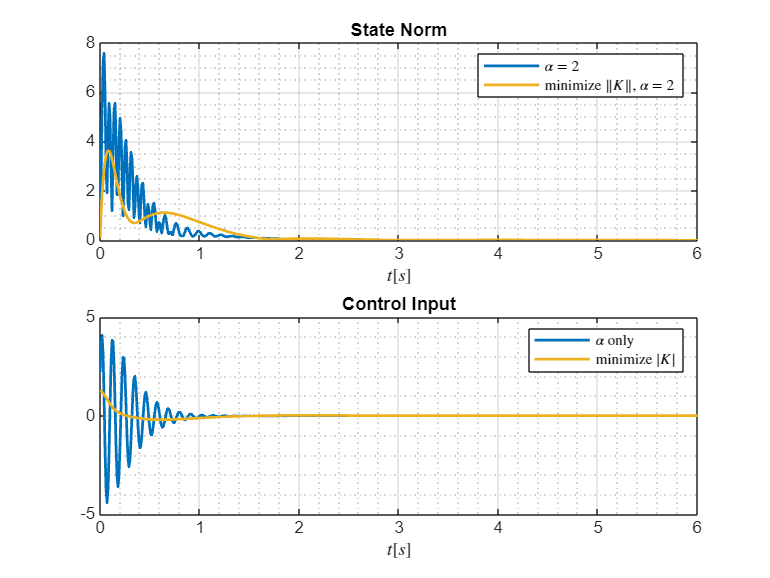

% -- State norm evolution over time
normX_b = vecnorm(simQ_b');
normX_c = vecnorm(simQ_c');
% -- Input evolution over time
u_b = (K_b*simQ_b')';
u_c = (K_c*simQ_c')';

% % State Norm
%% Plot 1
figure(1)
subplot(211)
plot(simT_b,normX_b, 'Color',[0 .4470 .7410], 'LineWidth',1.5)
hold on
plot(simT_c,normX_c, 'Color',[.9290 .6940 .1250], 'LineWidth',1.5)
grid on
grid minor
legend({'$\alpha = 2$', 'minimize $\|K\|$,  $\alpha = 2$'}, 'interpreter', 'latex')
title('State Norm')
xlabel('$t[s]$', 'interpreter', 'latex')
subplot(212)
plot(simT_b,u_b, 'Color',[0 .4470 .7410], 'LineWidth',1.5)
hold on
plot(simT_c,u_c, 'Color',[.9290 .6940 .1250], 'LineWidth',1.5)
grid on
grid minor
legend('$\alpha$ only','minimize $|K|$', 'interpreter', 'latex')
title('Control Input')
xlabel('$t[s]$', 'interpreter', 'latex')

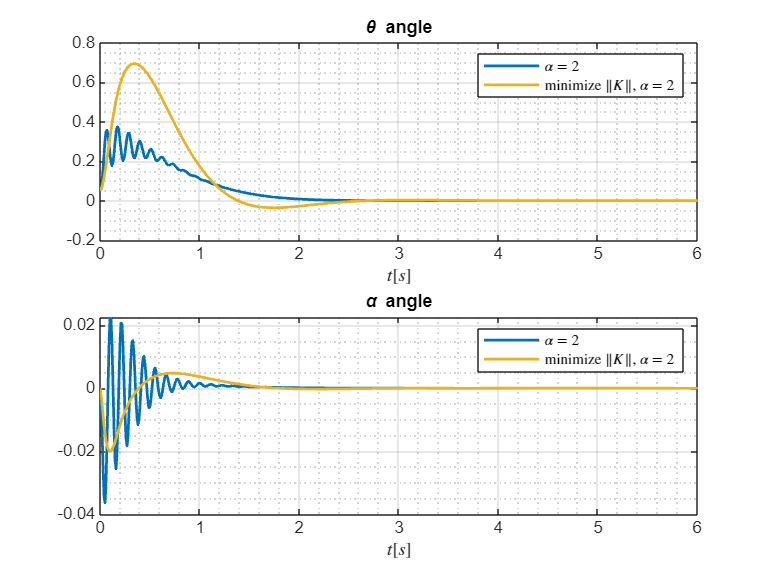

%% Plot theta
figure(2)
subplot(211)
plot(simT_b,simQ_b(:,1), 'Color',[0 .4470 .7410], 'LineWidth',1.5)
hold on
plot(simT_c,simQ_c(:,1), 'Color',[.9290 .6940 .1250], 'LineWidth',1.5)
grid on
grid minor
legend({'$\alpha = 2$', 'minimize $\|K\|$,  $\alpha = 2$'}, 'interpreter', 'latex')
title('\theta angle')
xlabel('$t[s]$', 'interpreter', 'latex')


% % Alpha
subplot(212)
plot(simT_b,simQ_b(:,2), 'Color',[0 .4470 .7410], 'LineWidth',1.5)
hold on
plot(simT_c,simQ_c(:,2), 'Color',[.9290 .6940 .1250], 'LineWidth',1.5)
grid on
grid minor
legend({'$\alpha = 2$', 'minimize $\|K\|$,  $\alpha = 2$'}, 'interpreter', 'latex')
title('\alpha angle')
xlabel('$t[s]$', 'interpreter', 'latex')

Question: Compute the **overshoot M** corresponding to the closed-loop matrix A + BK for the two gain matrices K computed in the previous step. Plot the exponential bound on the trajectories of the previous point. Does the exponential bound hold also for the solutions of the nonlinear system? (1pt)

T_sim = 0:0.01:6;


real_eigvals = real(eig(A+B*K_b))

real_eigvals =    -5.0814
   -5.0814
   -2.3464
   -2.3464



% Find the maximum and minimum real parts of the eigenvalues
lambda_M = max(real_eigvals)

lambda_M = -2.3464

lambda_m = min(real_eigvals)

lambda_m = -5.0814


% Compute the square root of the ratio of the maximum to minimum eigenvalues
M_b = sqrt(max(eig(P_b))/min(eig(P_b)))

M_b = 3.6174e+04

M_c = sqrt(k_c)

M_c = 4.0826e+03

x_bound1 = M_b*norm(q0)*exp(-2*T_sim)

x_bound1 = 1.0e+03 *

    2.8253    2.7693    2.7145    2.6607    2.6080    2.5564    2.5058    2.4562    2.4075    2.3598    2.3131    2.2673    2.2224    2.1784    2.1353    2.0930    2.0516    2.0109    1.9711    1.9321    1.8938    1.8563    1.8196    1.7835    1.7482    1.7136    1.6797    1.6464    1.6138    1.5819    1.5505    1.5198    1.4897    1.4602    1.4313    1.4030    1.3752    1.3480    1.3213    1.2951    1.2695    1.2443    1.2197    1.1955    1.1719    1.1487    1.1259    1.1036    1.0818    1.0603


x_bound2 = M_c*norm(q0)*exp(-2*T_sim)

x_bound2 =   318.8628  312.5489  306.3601  300.2937  294.3475  288.5190  282.8060  277.2060  271.7170  266.3366  261.0628  255.8934  250.8264  245.8597  240.9914  236.2194  231.5419  226.9571  222.4631  218.0580  213.7402  209.5078  205.3593  201.2929  197.3070  193.4001  189.5705  185.8168  182.1373  178.5308  174.9956  171.5305  168.1340  164.8047  161.5413  158.3426  155.2072  152.1339  149.1214  146.1686  143.2743  140.4373  137.6564  134.9307  132.2589  129.6400  127.0729  124.5567  122.0903  119.6728


**Plotting the solutions**

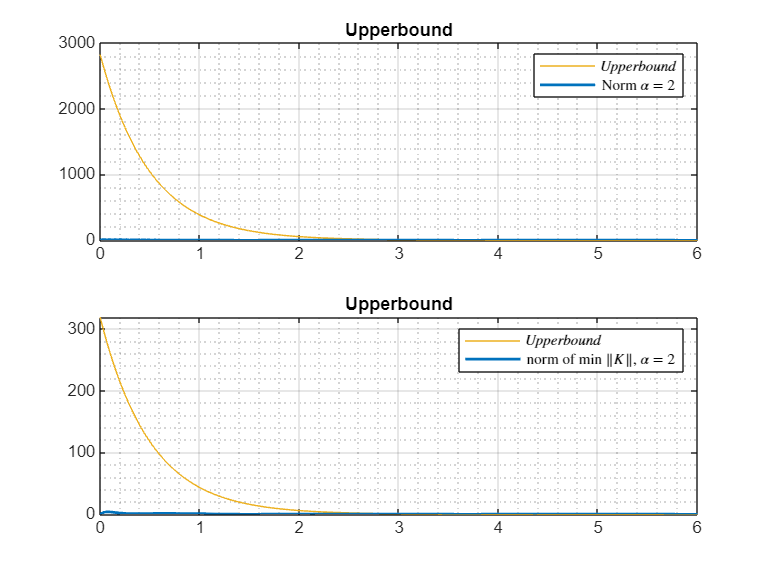

figure()
subplot(211)
plot(T_sim, x_bound1, 'Color',[.9290 .6940 .1250]); 
hold on
plot(simT_b,normX_b, 'Color',[0 .4470 .7410], 'LineWidth',1.5)

legend({'$Upperbound$', 'Norm $\alpha = 2$'}, 'interpreter', 'latex')
grid on
grid minor
title('Upperbound')

subplot(212)
plot(T_sim, x_bound2, 'Color',[.9290 .6940 .1250]); 
hold on

plot(simT_b,normX_c, 'Color',[0 .4470 .7410], 'LineWidth',1.5)
legend({'$Upperbound$', 'norm of min $\|K\|$,  $\alpha = 2$'}, 'interpreter', 'latex')
grid on
grid minor
title('Upperbound')